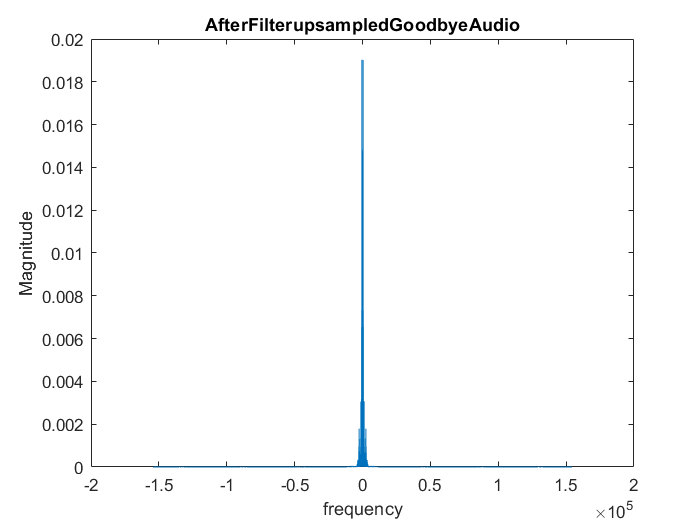

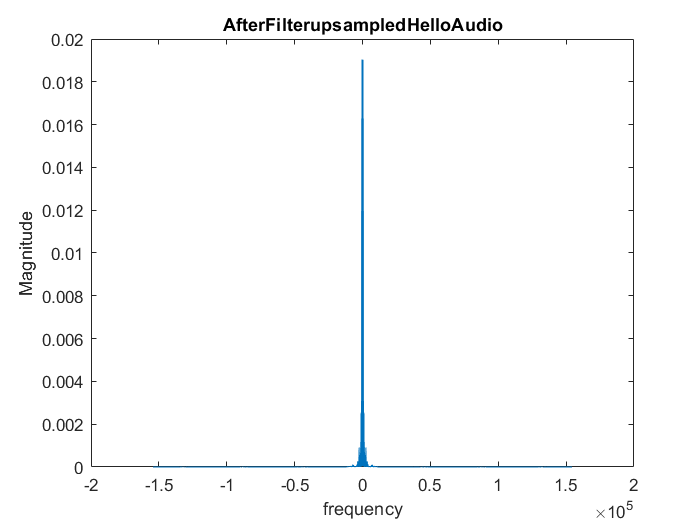

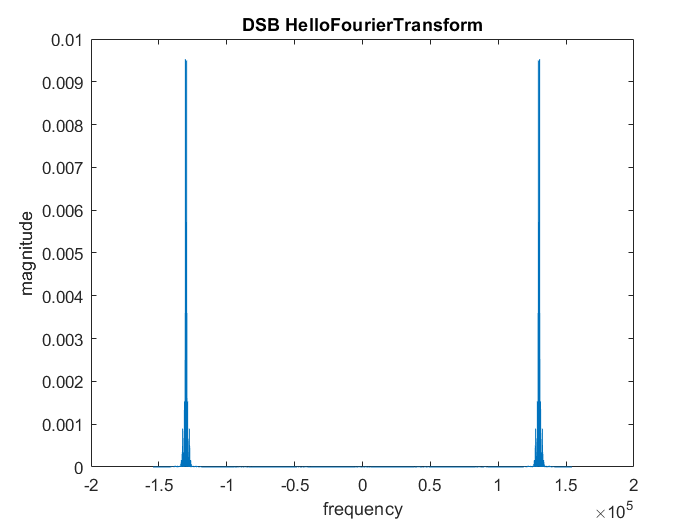

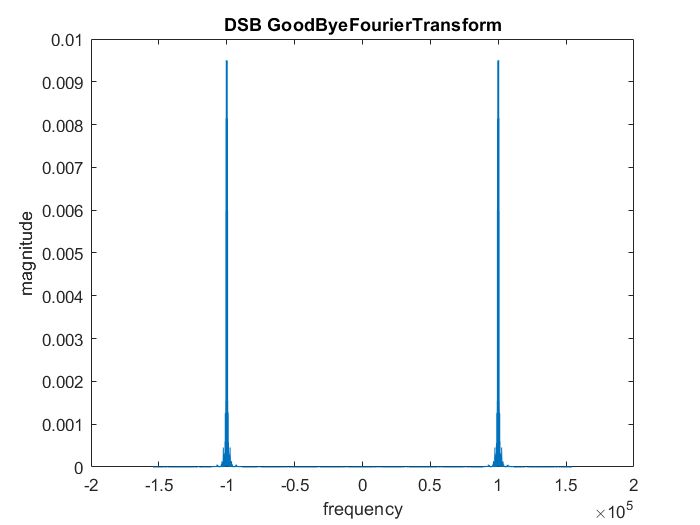

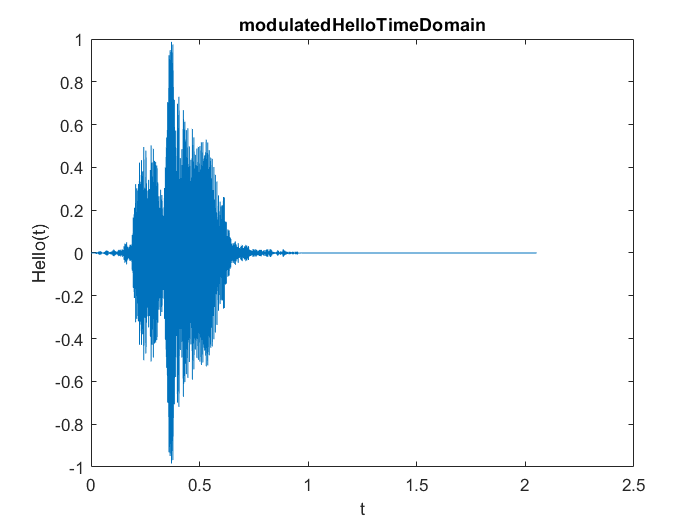

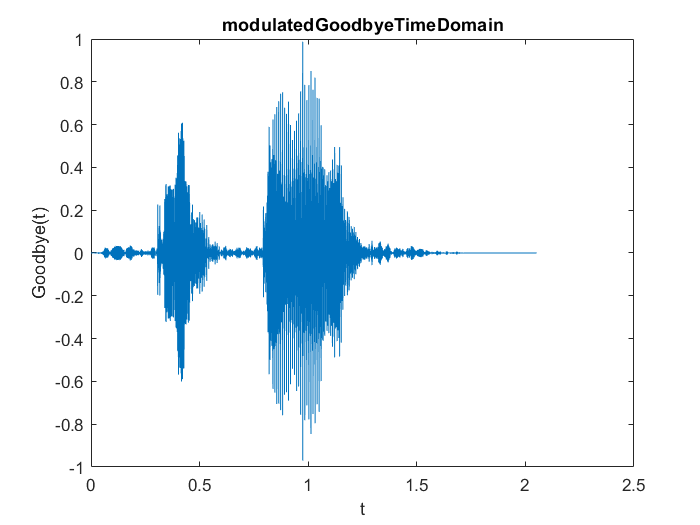

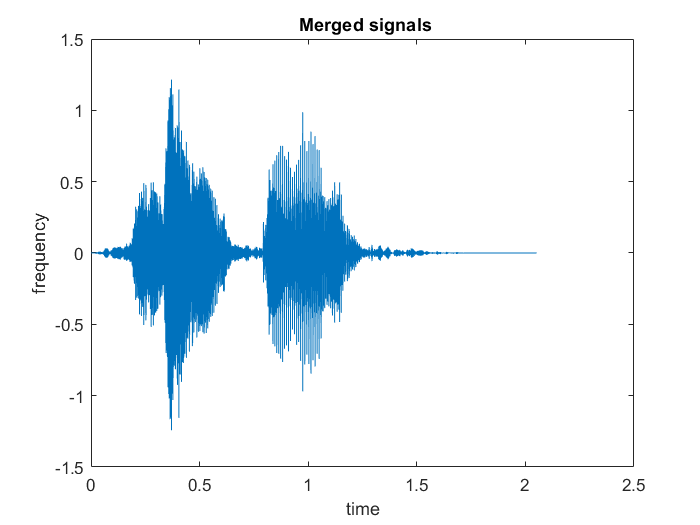

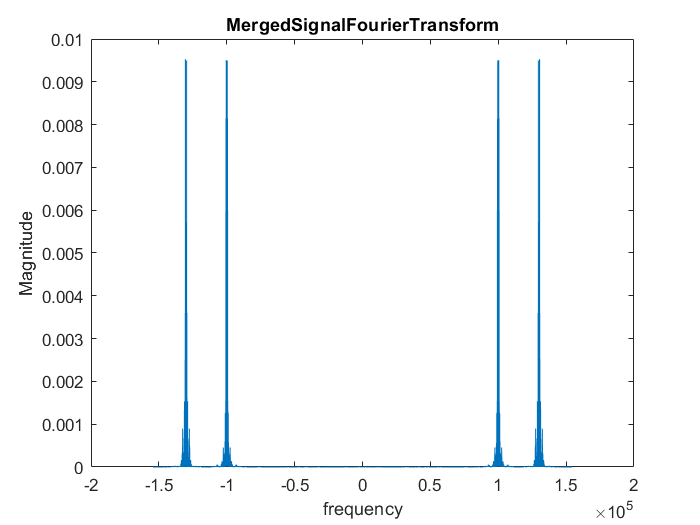

errorInTimeDomain = 0.0305

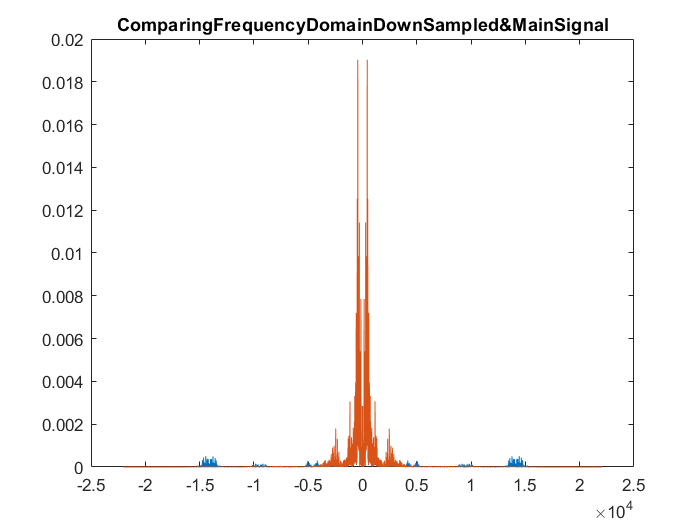

errorInFreqDomain = 3.4843e-09

%% Question 4

clc;
[helloSignal,Fs1] = audioread('Hello.mp3');
[goodbyeSignal,Fs2] = audioread('Goodbye.mp3');
GoodByeSignal=(goodbyeSignal(:,1)+goodbyeSignal(:,2))/2;
HelloSignal=(helloSignal(:,1)+helloSignal(:,2))/2;
% note : sampling frequency is same for both signals.
t = (1:length(HelloSignal))/Fs1;
figure();
subplot(2,1,1)
plot(t,GoodByeSignal);
title('GoodbyeTimeDomain');
ylabel('GoodBye(t)');
xlabel('time');
subplot(2,1,2)
plot(t,HelloSignal);
title('HelloTimeDomain');
ylabel('Hello(t)');
xlabel('time');
[HelloFourierTransform,helloFreqDomain] = standardFourierTransform(HelloSignal,Fs2);
[GoodByeFourierTransform,goodByeFreqDomain] = standardFourierTransform(GoodByeSignal,Fs1);
figure();
subplot(2,1,1)
plot(goodByeFreqDomain,abs(GoodByeFourierTransform));
title('GoodbyeFreqDomain');
ylabel('Magnitude');
xlabel('frequency');
subplot(2,1,2)
plot(helloFreqDomain,abs(HelloFourierTransform));
title('HelloFreqDomain');
ylabel('Magnitude');
xlabel('frequency');

%% calculating BoundWidth... (99 percent energy)
audioDataSdf = sdf(transpose(HelloSignal));
powerAbs = abs(audioDataSdf);
totalEnergy = sum(powerAbs);
maxPower = max(powerAbs);
peakEnergy = find(powerAbs == maxPower);
centerFrequency = mean(peakEnergy);
power99 = totalEnergy*0.99;
freqIterator = 1000;% 1kHz
boundedEnergy = calEnergy(powerAbs,centerFrequency,freqIterator);
while boundedEnergy < power99
    freqIterator = freqIterator + 1;
    boundedEnergy = calEnergy(powerAbs,centerFrequency,freqIterator);
end
startBound = centerFrequency - freqIterator;
endBound = centerFrequency + freqIterator;
BWhello = helloFreqDomain(endBound)-helloFreqDomain(startBound)/2
audioDataSdf = sdf(transpose(GoodByeSignal));
powerAbs = abs(audioDataSdf);
totalEnergy = sum(powerAbs);
maxPower = max(powerAbs);
peakEnergy = find(powerAbs == maxPower);
centerFrequency = mean(peakEnergy);
power99 = totalEnergy*0.99;
freqIterator = 1000;% 1kHz
boundedEnergy = calEnergy(powerAbs,centerFrequency,freqIterator);
while boundedEnergy < power99
    freqIterator = freqIterator + 1;
    boundedEnergy = calEnergy(powerAbs,centerFrequency,freqIterator);
end
startBound = centerFrequency - freqIterator;
endBound = centerFrequency + freqIterator;
BWgoodbye = goodByeFreqDomain(endBound)-goodByeFreqDomain(startBound)/2

%% upsampling signals

% 103*2k/44.1k = 5.89 -> at least we should upsample 6 times upper
% in order to avoid disturbance's occurance we use 7 instead.

upsamplingIntegerFactor = 7;
fsAfterUpsampling = Fs1*upsamplingIntegerFactor; % note Fs1=Fs2
upsampledHello = upsamplingIntegerFactor.*upsample(HelloSignal,upsamplingIntegerFactor);
upsampledGoodBye = upsamplingIntegerFactor.* upsample(GoodByeSignal,upsamplingIntegerFactor);

[upsampledHelloFourierTransform,upsampledhelloFreqDomain] = standardFourierTransform(upsampledHello,fsAfterUpsampling);
[upsampledGoodByeFourierTransform,upsampledgoodByeFreqDomain] = standardFourierTransform(upsampledGoodBye,fsAfterUpsampling);
figure();
subplot(2,1,1)
plot(upsampledhelloFreqDomain,abs(upsampledGoodByeFourierTransform));
title('upsampledGoodbyeAudio');
ylabel('Magnitude');
xlabel('frequency');
subplot(2,1,2)
plot(upsampledgoodByeFreqDomain,abs(upsampledHelloFourierTransform));
title('upsampledHelloAudio');
ylabel('Magnitude');
xlabel('frequency');

% loading designed filter
load('HdUpsamplingFilter.mat')
filteredUpsampledHello= filter(Hd,upsampledHello);
filteredUpsampledGoodBye= filter(Hd,upsampledGoodBye);

[AfterFilterupsampledHelloFourierTransform,AfterFilterupsampledhelloFreqDomain] = standardFourierTransform(filteredUpsampledHello,fsAfterUpsampling);
[AfterFilterupsampledGoodByeFourierTransform,AfterFilterupsampledgoodByeFreqDomain] = standardFourierTransform(filteredUpsampledGoodBye,fsAfterUpsampling);

figure
plot(AfterFilterupsampledhelloFreqDomain,abs(AfterFilterupsampledHelloFourierTransform));
title('AfterFilterupsampledGoodbyeAudio');
ylabel('Magnitude');
xlabel('frequency');
plot(AfterFilterupsampledgoodByeFreqDomain,abs(AfterFilterupsampledGoodByeFourierTransform));
title('AfterFilterupsampledHelloAudio');
ylabel('Magnitude');
xlabel('frequency');

time = (1:length(filteredUpsampledHello))/fsAfterUpsampling;
firstCarrierFrequency = 130000;
firstCarrier = cos(2*pi*firstCarrierFrequency*time);
secondCarrierFrequency = 100000;
secondCarrier = cos(2*pi*secondCarrierFrequency*time);
% DSB modulating
v_Hello = firstCarrier.*(transpose(filteredUpsampledHello));
v_GoodBye = secondCarrier.*(transpose(filteredUpsampledGoodBye));

[DSBhelloFourierTransform,dsbHelloFreq] = standardFourierTransform(v_Hello,fsAfterUpsampling);
[DSBgoodByeFourierTransform,dsbGoodByeFreq] = standardFourierTransform(v_GoodBye,fsAfterUpsampling);
figure()
plot(dsbHelloFreq,abs(DSBhelloFourierTransform));
title('DSB HelloFourierTransform');
xlabel('frequency');
ylabel('magnitude');
figure()
plot(dsbGoodByeFreq,abs(DSBgoodByeFourierTransform));
title('DSB GoodByeFourierTransform');
xlabel('frequency');
ylabel('magnitude');

mergedSendingMessage = v_Hello+v_GoodBye;
figure
plot(time,v_Hello);
title('modulatedHelloTimeDomain');
xlabel('t');
ylabel('Hello(t)')
figure
plot(time,v_GoodBye);
title('modulatedGoodbyeTimeDomain')
xlabel('t');
ylabel('Goodbye(t)')
figure();
plot(time,mergedSendingMessage);
title(' Merged signals');
xlabel('time');
ylabel('frequency');
[mergedSignalFourierTransform,mergedSignalFreq] = standardFourierTransform(mergedSendingMessage,fsAfterUpsampling);
figure();
plot(mergedSignalFreq,abs(mergedSignalFourierTransform));
title('MergedSignalFourierTransform');
xlabel('frequency');
ylabel('Magnitude');

%% demodulating
demodulated = 2.*firstCarrier.*mergedSendingMessage; % Gain 2 inOrder synching %demodulated Signal’s amplitude to it’s main Amplitude.

figure();
plot(time,demodulated);
title('DemodulatedSignal');
xlabel('time');
ylabel('Magnitude');
[demodSignalFourierTransform,demodFreq] = standardFourierTransform(demodulated,fsAfterUpsampling);
figure();
plot(demodFreq,abs(demodSignalFourierTransform));
title('demodulatedSignalFourierTransform');
xlabel('frequency');
ylabel('Magnitude');

%% Butterworth filter ->LowPass filtering the modulated Data
[numerator,denumerator] = butter(1,BWhello/fsAfterUpsampling);
figure();
freqz(numerator,denumerator);
title('Butter Filter: (ordrer = 5,normalizedFrequency)')
afterLossPass = filter(numerator,denumerator,demodulated);
figure();
plot(time,afterLossPass);
title('FilteredDataButterworth butterOrder = 1');
xlabel('time');
ylabel('Magnitude');
[afterLowPassFourierTransform,afterLowPassFreqDomain] = standardFourierTransform(afterLossPass,fsAfterUpsampling);
figure();
plot(afterLowPassFreqDomain,abs(afterLowPassFourierTransform));
title('filteredSignalFourierTransform ButterOrder = 1');
xlabel('frequency');
ylabel('Magnitude');

%% down sampeling
downSampledOutput = downsample(afterLossPass,upsamplingIntegerFactor);
tDownSampled = (1:length(downSampledOutput))/Fs1;
figure();
plot(tDownSampled,downSampledOutput);
title('downSampledSignal');
xlabel('time');
ylabel('Magnitude');
[downSampledFourierTransform,downSampledFreqDomain] = standardFourierTransform(downSampledOutput,Fs1);
figure();
plot(downSampledFreqDomain,abs(downSampledFourierTransform));
title('downSampledFourierTransform');
xlabel('frequency');
ylabel('Magnitude');

%% comparing results
% first in time domain we compare them
figure();
plot(t,HelloSignal);
hold on
plot(tDownSampled,downSampledOutput);
title('ComparingTimeDomainDownSampled&MainSignal');
errorInTimeDomain=immse(downSampledOutput,transpose(HelloSignal))

figure();
plot(downSampledFreqDomain,abs(downSampledFourierTransform));
hold on
plot(helloFreqDomain,abs(HelloFourierTransform));
title('ComparingFrequencyDomainDownSampled&MainSignal');
errorInFreqDomain=immse(abs(transpose(HelloFourierTransform)),abs(downSampledFourierTransform))

function [out,standardDomain] = standardFourierTransform(signal,fs)
n = length(signal);
fourier=fft(signal,n);
fourier = fourier/fs;
out = fftshift(fourier);
domain = linspace(-pi,pi,length(out));
standardDomain = domain*fs/(2*pi);
end

function [out,Tsignal] = sdf(signal)
Tsignal = fourierDiscreteStandardTransform(signal);
out = Tsignal.*conj(Tsignal);
end

function out = fourierDiscreteStandardTransform(signal)
out = fftshift(fft(signal,size(signal,2)));
end


function boundedEnergy = calEnergy(powerSignal,center,range)
boundedEnergy = sum(powerSignal(center-range:center+range));
end
